# Calculate the soil backscattering using the **Bare Soil Model** (**BSM**) Constructed

**BSM: **$\sigma =A\left(\theta \right)\mathrm{ln}\left(\mathrm{SM}\right)+\mathrm{Bln}\left(\theta \right)\left(\mathrm{Zs}\right)+C\left(\theta \right)$

In the model: $\theta$ is the incidence angle, SM is the soil moisture with  unit $\frac{m^{3\text{\,}} }{m^3 }$ ,Zs is the roughness parameter that equals $\frac{s^2 }{l}$; A, B and C see indices_model.mat.

Soil Moisture data, refer to datasets_to_build_WCM/soil_moisture folder with unit  as percentage. SM should divide 100 to change Unit to $\frac{m^3 }{m^3 }$.% 

% Data preparation
clear,clc
% filefolder = 'G:\lincoln_INB_backup\Water Cloud Model\';
filefolder = [pwd,'\'];
addpath(genpath(filefolder))
load([filefolder 'datasets_to_build_WCM\soil_moisture\sm_all.mat'])

% SM measurements of 25 samples
VSM1010 = sm_all(:,1)/100;
VSM1022 = sm_all(:,2)/100;
VSM1104 = sm_all(:,3)/100;
VSM1116 = sm_all(:,4)/100

VSM1116 =     0.1750
    0.1800
    0.1620
    0.1300
    0.1590
    0.1780
    0.1890
    0.1880
    0.1190
    0.1350


VSM0328 = sm_all(:,5)/100;
VSM0409 = sm_all(:,6)/100;
VSM0503 = sm_all(:,7)/100;
VSM0515 = sm_all(:,8)/100;

VSMall = cat(1,VSM1010,VSM1022,VSM1104,VSM1116,VSM0328,VSM0409,VSM0503,VSM0515);


Calculate tje rows and colomns of the sample sits corresponding

% resize the data, factor = 0.53905
load([filefolder 'datasets_to_build_WCM\row_column_samples.mat'])
colomns = round(column_samples*0.53905);
rows = round(row_samples*0.53905);

Extract Indices of BSM model (A, B, C)

% extract the corresponding indices of the model to each samples
load([filefolder 'datasets_to_build_WCM\indices_model.mat'])

% define indices
indA = nan(25,1);
indB = nan(25,1);
indC = nan(25,1);

for i=1:25
    indA(i)= a(rows(i),colomns(i));
    indB(i)= b(rows(i),colomns(i));
    indC(i)= c(rows(i),colomns(i));
end

Extract roughness according to the sample locations

load([filefolder 'datasets_to_build_WCM\soilroughness_roi_12.mat'])
% soil roughness (SR)
SR = soilroughness_roi;
SRall = repmat(SR,8,1);

Extract angle of the locations

load([filefolder 'datasets_to_build_WCM\incidence_angle.mat'])
% Incidence Angle (IA)
IA = nan(25,1);
for i=1:25
    IA(i)= theta1103_roi_rs(rows(i),colomns(i));
end

Calculating the soil backscattering According to the model

DB_soil1010 = indA.*log(VSM1010)+indB.*log(SR)+indC;
DB_soil1022 = indA.*log(VSM1022)+indB.*log(SR)+indC;
DB_soil1104 = indA.*log(VSM1104)+indB.*log(SR)+indC;
DB_soil1116 = indA.*log(VSM1116)+indB.*log(SR)+indC;
DB_soil0328 = indA.*log(VSM0328)+indB.*log(SR)+indC;
DB_soil0409 = indA.*log(VSM0409)+indB.*log(SR)+indC;
DB_soil0503 = indA.*log(VSM0503)+indB.*log(SR)+indC;
DB_soil0515 = indA.*log(VSM0515)+indB.*log(SR)+indC;
DB_soil = cat(1,DB_soil1010,DB_soil1022,DB_soil1104,DB_soil1116,... 
DB_soil0328,DB_soil0409,DB_soil0503,DB_soil0515);

Read S1B satellite canopy backscattering

load([filefolder 'datasets_to_build_WCM\db_roi_all.mat'])
db_roi = reshape(db_roi_all,200,1);

Construct Water Cloud Model (solve the coefficients of the Model, a and b)

Step 1: normalizing the backscattering to a certain angle (40 degrees)

Normalizing equation: $\sigma^{\mathrm{ref}} =\sigma \frac{{\mathrm{cos}}^2 \left(\theta^{\mathrm{ref}} \right)}{{\mathrm{cos}}^2 \left(\theta \right)}$

% normalizing factor
Nor_factor = cos(40/180*pi)^2./cos(IA/180*pi).^2;
Nor_factor2 = repmat(Nor_factor,8,1);

% db to ratio
db_roi_ratio = 10.^(db_roi/10); 
DB_soil_ratio = 10.^(DB_soil/10);

% normalizing
db_roi_ratio = db_roi_ratio.*Nor_factor2;
DB_soil_ratio = DB_soil_ratio.*Nor_factor2;

% ratio to db
dbN_roi = 10*log10(db_roi_ratio);
dbN_soil = 10*log10(DB_soil_ratio);

STEP 2: load wheat water conternt data, with unit as $\frac{g}{m^2 }$

% use the averaged value to represent the wheat water content
load wheat_water_content_with_the_first_four_times_not_correct.mat
% WWC_averaged = [0.0,65.0,190.3,239.3,212.0,566.7,3741.7,3647.9];
% WWCall = cat(1,WWC0328,WWC0409,WWC0503,WWC0515);
% WWC2_averaged = repelem(WWC_averaged',25);
WWC2_averaged = reshape(wheat_water_content,200,1);

STEP 3: Abstract 150 as  the samples to construct the model

% produce 150 samples randomly
randsamples = sort(randperm(200,150));
% extract the samples that solve water clound model
DBN_S1B_abs = dbN_roi(randsamples);
DBN_soil_abs = dbN_soil(randsamples);
WWC_abs = WWC2_averaged(randsamples);

% get the rest samples
Ind_val = ~ismember(1:200,randsamples);
% extract the samples that validate water clound model
DBN_S1B_val = dbN_roi(Ind_val);
DBN_soil_val = dbN_soil(Ind_val);
WWC_val = WWC2_averaged(Ind_val);

% soil moisture and soil roughness to be validate
VSM_val = VSMall(Ind_val);
SR_val = SRall(Ind_val);

STEP 4: solve the model indeces

% delete nan data
Ind_nan = isnan(WWC_abs)|isnan(DBN_soil_abs)|isnan(DBN_S1B_abs);
% cos(theta) and data preparation
T = cos(40/180*pi);
xData = WWC_abs(~Ind_nan)/1000;
yData = DBN_soil_abs(~Ind_nan);
zData = DBN_S1B_abs(~Ind_nan);

% yData abd zData to ratio
yDataR = 10.^(yData/10);
zDataR = 10.^(zData/10);

% [xData,yData,zData] = prepareSurfaceData(WWC_abs,DBN_soil_abs,DBN_S1B_abs);
% fitting equation
ft = fittype( 'a*x*0.766*(1-exp(-2*b*x/0.766))+exp(-2*b*x/0.766)*y', ...
    'independent', {'x', 'y'}, 'dependent', 'z' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0 0.0];

% solve the equation
[fitresult, gof] = fit( [xData, yDataR], zDataR, ft, opts );

Plot the model-1

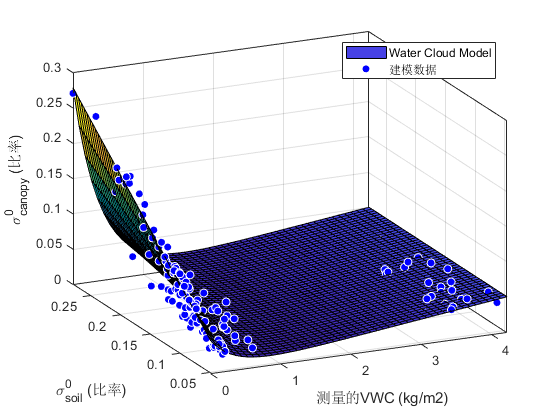

% Plot fit with data.
% figure( 'Name', 'Water Cloud Model' );
% h = plot( fitresult, [xData, yDataR], zDataR );
% legend( h, 'Water Cloud Model', ' vs. xData, yData', 'Location', 'NorthEast' );
% % Label axes
% xlabel 'Wheat Water Content (kg/m^2)'
% ylabel 'Soil Backscattering'
% zlabel 'Canopy Backscattering'
% grid on
% view( -37.9, 18.0 );

% Plot fit with data.
figure( 'Name', 'Water Cloud Model' );
h = plot( fitresult, [xData, yDataR], zDataR );
legend( h, 'Water Cloud Model', '建模数据', 'Location', 'NorthEast' );
% Label axes
xlabel '测量的VWC (kg/m2)'
ylabel '\sigma_{soil}^0 (比率)'
zlabel '\sigma_{canopy}^0 (比率)'
grid on
view( -25, 25 );

Plot model-2

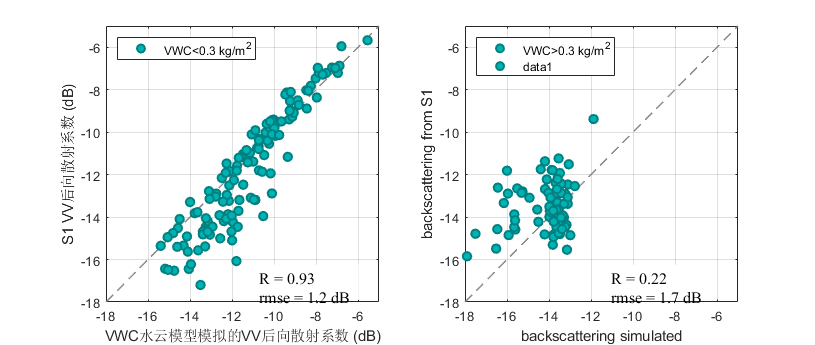

rng('shuffle')
rand100 = randi([1, 200], 1, 150);
rand100 = sort(rand100);

a = fitresult.a; %0.01554;
b = fitresult.b; %0.9268;
db_S1 = db_roi_ratio;
x = WWC2_averaged/1000;
y = DB_soil_ratio;
db_simulated = a*x*0.766.*(1-exp(-2*b*x/0.766))+exp(-2*b*x/0.766).*y;

% scatter(db_simulated,db_S1,25,x*1000,'filled')
scatter(db_simulated,db_S1,40,'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)
xlabel 'backscattering simulated'
ylabel 'backscattering from S1'
box on
grid on


% DB
figure('position',[1834 340 577 505])

plot([-18,0],[-18,0],'--',...
    'LineWidth',1,'Color',[0.5,0.5,0.5])
hold on

db_simulated_db = 10*log10(db_simulated);
db_S1_db = 10*log10(db_S1);

h1 = scatter(db_simulated_db(rand100),db_S1_db(rand100),40,'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)

h1 =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: [0 0.5000 0.5000]
    MarkerFaceColor: [0 0.7000 0.7000]
           SizeData: 40
          LineWidth: 1.5000
              XData: [1×150 double]
              YData: [1×150 double]
              ZData: [1×0 double]
              CData: [0.8500 0.3250 0.0980]

  显示 所有属性


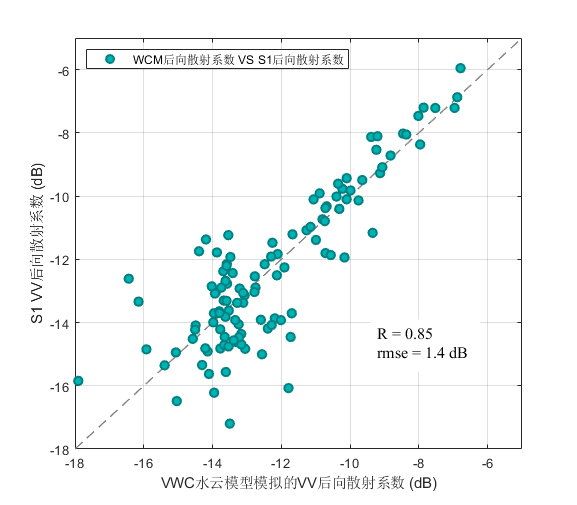

set(gca,'xlim',[-18,-5],'ylim',[-18,-5])
xlabel 'VWC水云模型模拟的VV后向散射系数 (dB)'
ylabel 'S1 VV后向散射系数 (dB)'
box on
grid on

% 
legend(h1,{'WCM后向散射系数 VS S1后向散射系数'},...
    'location','northwest')

% statistical parameters
annotation(gcf,'textbox',...
    [0.641975308641975 0.264346537132074 0.190476185325172 0.102970294551094],...
    'String',{'R = 0.85','rmse = 1.4 dB'},...
    'LineStyle','none',...
    'FontSize',12,...
    'FontName','Times New Roman',...
    'BackgroundColor',[1 1 1]);


% 计算统计参数：2019年1月18日
R = corrcoef(db_simulated_db(rand100'),db_S1_db(rand100))

R =     1.0000    0.8665
    0.8665    1.0000


sqrt(mean((db_simulated_db(rand100)-db_S1_db(rand100)).^2))

ans = 1.2162

对比不同条件下水云模型的适应性；2019年1月18日

Ismall = WWC2_averaged<300;
figure('position',[1834 340 815 345])
subplot(1,2,1)
plot([-18,0],[-18,0],'--',...
    'LineWidth',1,'Color',[0.5,0.5,0.5])
hold on


h1 = scatter(db_simulated_db(Ismall),db_S1_db(Ismall),40,'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)

h1 =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: [0 0.5000 0.5000]
    MarkerFaceColor: [0 0.7000 0.7000]
           SizeData: 40
          LineWidth: 1.5000
              XData: [1×125 double]
              YData: [1×125 double]
              ZData: [1×0 double]
              CData: [0.8500 0.3250 0.0980]

  显示 所有属性


          
set(gca,'xlim',[-18,-5],'ylim',[-18,-5])
xlabel 'VWC水云模型模拟的VV后向散射系数 (dB)'
ylabel 'S1 VV后向散射系数 (dB)'
box on
grid on

% 
legend(h1,{'VWC<0.3 kg/m^2'},...
    'location','northwest')

% statistical parameters
annotation(gcf,'textbox',...
    [0.31 0.13 0.13 0.102970294551094],...
    'String',{'R = 0.93','rmse = 1.2 dB'},...
    'LineStyle','none',...
    'FontSize',12,...
    'FontName','Times New Roman',...
    'BackgroundColor',[1 1 1]);

% 计算统计参数：2019年1月18日
R1 = corrcoef(db_simulated_db(Ismall),db_S1_db(Ismall))

R1 =     1.0000    0.9265
    0.9265    1.0000


sqrt(mean((db_simulated_db(Ismall)-db_S1_db(Ismall)).^2))

ans = 1.2630


subplot(1,2,2)
plot([-18,0],[-18,0],'--',...
    'LineWidth',1,'Color',[0.5,0.5,0.5])
hold on


h1 = scatter(db_simulated_db(~Ismall),db_S1_db(~Ismall),40,'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)

h1 =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: [0 0.5000 0.5000]
    MarkerFaceColor: [0 0.7000 0.7000]
           SizeData: 40
          LineWidth: 1.5000
              XData: [1×75 double]
              YData: [1×75 double]
              ZData: [1×0 double]
              CData: [0.8500 0.3250 0.0980]

  显示 所有属性


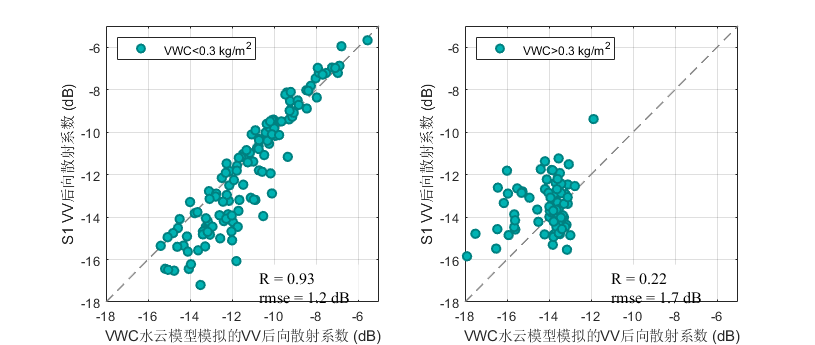

          
set(gca,'xlim',[-18,-5],'ylim',[-18,-5])
xlabel 'VWC水云模型模拟的VV后向散射系数 (dB)'
ylabel 'S1 VV后向散射系数 (dB)'
box on
grid on

% 
legend(h1,{'VWC>0.3 kg/m^2'},...
    'location','northwest')

% statistical parameters
annotation(gcf,'textbox',...
    [0.741975308641975 0.13 0.13 0.102970294551094],...
    'String',{'R = 0.22','rmse = 1.7 dB'},...
    'LineStyle','none',...
    'FontSize',12,...
    'FontName','Times New Roman',...
    'BackgroundColor',[1 1 1]);


% 计算统计参数：2019年1月18日
R2 = corrcoef(db_simulated_db(~Ismall),db_S1_db(~Ismall))

R2 =     1.0000    0.2756
    0.2756    1.0000


sqrt(mean((db_simulated_db(~Ismall)-db_S1_db(~Ismall)).^2))

ans = 1.5664

STEP 5: solve the backscattering

syms x y z
% eqn = a*x^2 + b*x + c == 0;
% sol = solve(eqn)
% sola = solve(eqn, a)
a = round(a,4);
b = round(b,3);

eqn = a*x*0.766*(1-exp(-2*b*x/0.766))+exp(-2*b*x/0.766)*y-z==0;
sola1 = solve(eqn, y)

$$sola1 = {\mathrm{e}}^{\frac{974\,x}{383}}\,\left(z+\frac{14937\,x\,\left({\mathrm{e}}^{-\frac{974\,x}{383}}-1\right)}{1250000}\right)$$


z = DBN_S1B_val;
x = WWC_val/1000;
z = z(~(isnan(z)|isnan(x)));
x = x(~(isnan(z)|isnan(x)));

% db to linear
zR = 10.^(z/10);

% when VWC is large, backscattering from soil cann't be solved;
Ivwc = x<3; % where vwc is smaller than 3 kg/m2
x = x(Ivwc);
zR = zR(Ivwc);
% yFit = exp((4634*x)/1915).*(zR + (297591*x.*(exp(-(4634*x)/1915) - 1))/25000000)
yFit = exp((954*x)/383).*(zR + (15703*x.*(exp(-(954*x)/383) - 1))/1250000)

yFit =     0.1270
    0.1293
    0.1900
    0.0961
    0.2006
    0.1538
    0.1815
    0.1781
    0.0704
    0.1957


Plot the result 

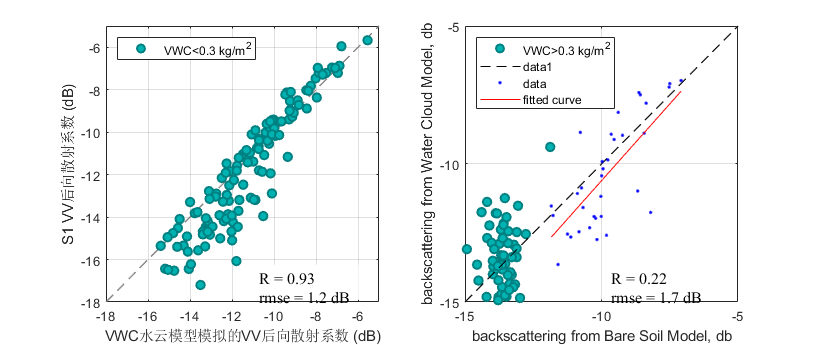

Ind2 = ~isnan(DBN_soil_val);
plot([-15,-5],[-15,-5],'k--')
hold on
% scatter(DBN_soil_val(Ind2),yFit(Ind2))
set(gca,'xlim',[-15,-5],'ylim',[-15,-5])

box on
% ratio to db
yFit(yFit<0)=0;

yFit_DB = 10*log10(yFit);

[xData, yData] = prepareCurveData(DBN_soil_val(Ivwc), yFit_DB);
ft = fittype( 'poly1' );
[fitresult, gof] = fit( xData, yData, ft );
h = plot( fitresult, xData, yData );
grid on

xlabel('backscattering from Bare Soil Model, db')
ylabel('backscattering from Water Cloud Model, db')

STEP 6: solve the soil moisture using the bare soil model

**BSM: **$\sigma =A\left(\theta \right)\mathrm{ln}\left(\mathrm{SM}\right)+\mathrm{Bln}\left(\theta \right)\left(\mathrm{Zs}\right)+C\left(\theta \right)$

A(40) = 2.5555; 

B(40) = 3.5974; 

C(40) = 3.7978;

% BSM equals
syms sm zs db
eqn = 2.5555*log(sm)+3.5974*log(zs)+3.7978-db==0;
% solve the equation
sola2 = solve(eqn, sm)

$$sola2 = \frac{{\mathrm{e}}^{\frac{2000\,\mathrm{db}}{5111}-\frac{37978}{25555}}}{{\mathrm{zs}}^{35974/25555}}$$


% sm solving equation
db = yFit_DB;
zs = SR_val(Ivwc);
sm = exp((2000*db)/5111 - 37978/25555)./zs.^(35974/25555);

Plot the soil mositure retrieved

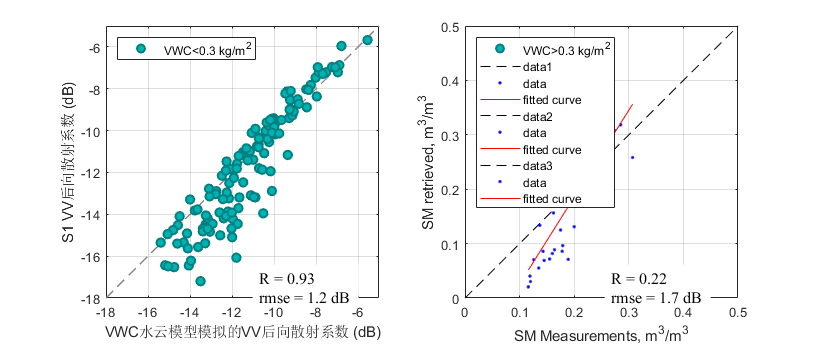

% treat sm > 0.4 as outlines
Ind3 = sm>0.4;
% sm_DO: soil moisture delete outlines
sm_DO = sm(~Ind3);
VSM_val_DO = VSM_val(~Ind3);
plot([0,0.5],[0,0.5],'k--')
hold on
% scatter(VSM_val_DO,sm_DO)
set(gca,'xlim',[0,0.5],'ylim',[0,0.5])

box on

[xData, yData] = prepareCurveData(VSM_val_DO, sm_DO );
ft = fittype( 'poly1' );
[fitresult, gof] = fit( xData, yData, ft );
h = plot( fitresult, xData, yData );
grid on
xlabel('SM Measurements, m^3/m^3')
ylabel('SM retrieved, m^3/m^3')

Plot the fitting curve

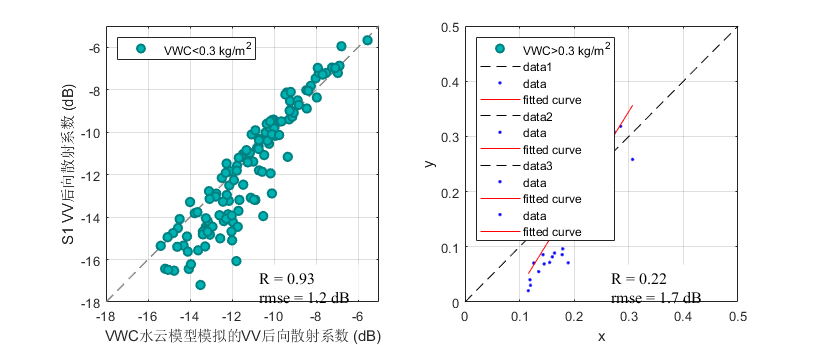

[xData, yData] = prepareCurveData( VSM_val_DO, sm_DO );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
% figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
% legend( h, 'sm_DO vs. VSM_val_DO', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
% xlabel VSM_val_DO
% ylabel sm_DO
grid on

retrieve soil moisture using all the samples

1 - Get soil contribution to the total signal

sola1 = exp((950*x)/383)*(z + (31023*x*(exp(-(950*x)/383) - 1))/2500000),

where, x is the vegetation water content in kg/m2, z is the canopy backscattering in linear

% when VWC is large, can't get soil contribution
% Vegetation water content, tests 1-6
sp = 125;
VWC2 = WWC2_averaged(1:sp)/1000;
% backscattering from S1
db_S1 = db_roi_ratio(1:sp);
% dbWCM_soil = exp((950*VWC2)/383).*(db_S1 + (31023*VWC2.*(exp(-(950*VWC2)/383) - 1))/2500000),
dbWCM_soil = exp((954*VWC2)/383).*(db_S1 + (15703*VWC2.*(exp(-(954*VWC2)/383) - 1))/1250000)

dbWCM_soil =     0.1270
    0.1293
    0.1900
    0.0882
    0.2055
    0.1901
    0.1456
    0.1793
    0.1146
    0.0788


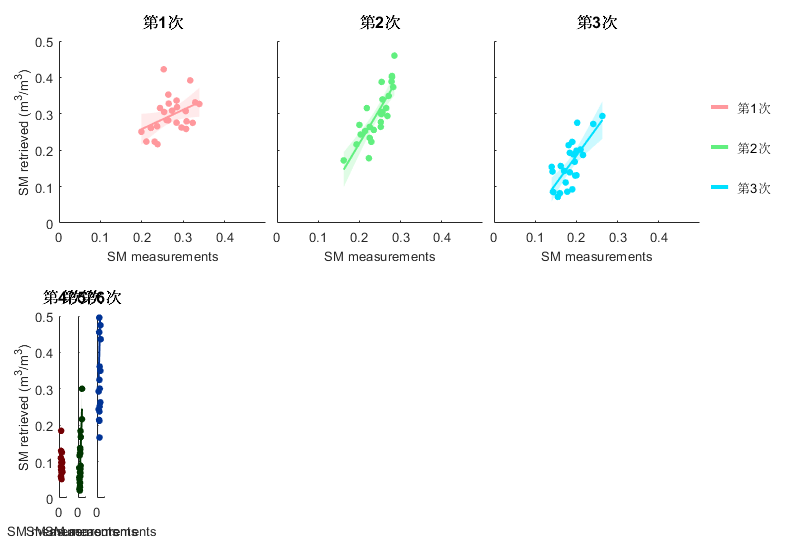


% compare db from WCM and db from IEM model
dbIEM_soil = DB_soil_ratio(1:sp);
scatter(dbIEM_soil,dbWCM_soil,25,'filled')
hold on
% plot figure

ft = fittype( 'poly1' );
[fitresult, gof] = fit(dbIEM_soil,dbWCM_soil, ft );
h = plot( fitresult);
grid on
box on
set(gca,'xlim',[0 0.3],'ylim',[0 0.3])

xlabel('backscattering from Bare Soil Model, db')
ylabel('backscattering from Water Cloud Model, db')

sola2 = exp((2000*db)/5111 - 37978/25555)/zs^(35974/25555)

where db is the soil backscattering and zs is the soil roughness

% soil roughness
zs = SRall(1:sp);
% soil contribution from WCM, NOTE: db!
db = 10*log10(dbWCM_soil);
smWCM = exp((2000*db)/5111 - 37978/25555)./zs.^(35974/25555);

% soil moisture measurements
smMea = VSMall(1:sp);

plot the results

figure('position',[ 910 286 567 505])
plot([0,0.5],[0,0.5],'--',...
    'LineWidth',1,'Color',[0.5,0.5,0.5])
hold on
h1 = scatter(smMea,smWCM,25,'filled')

h1 =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 25
          LineWidth: 0.5000
              XData: [1×150 double]
              YData: [1×150 double]
              ZData: [1×0 double]
              CData: [0.8500 0.3250 0.0980]

  显示 所有属性


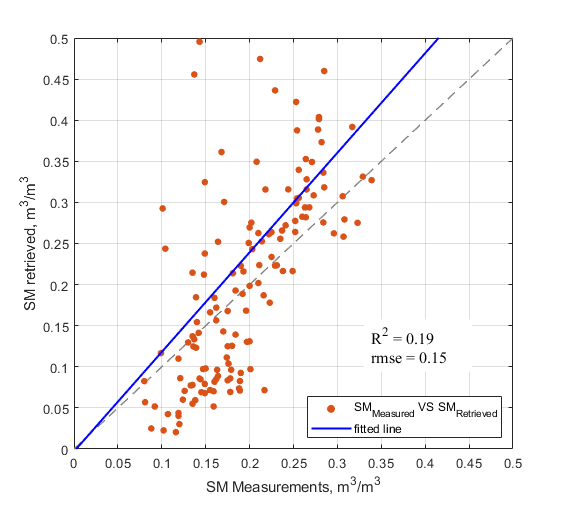


% plot figure
ft = fittype( 'poly1' );
[fitresult, gof] = fit(smMea,smWCM, ft );
h2 = plot(fitresult);
set(h2,'LineWidth',1.5,'Color','blue')
grid on
box on
set(gca,'xlim',[0 0.5],'ylim',[0 0.5])

xlabel('SM Measurements, m^3/m^3')
ylabel('SM retrieved, m^3/m^3')
legend([h1,h2],{'SM_{Measured} VS SM_{Retrieved}',...
    'fitted line'},'location','southeast')

% statistical parameters
annotation(gcf,'textbox',...
    [0.641975308641975 0.264346537132074 0.190476185325172 0.102970294551094],...
    'String',{'R^2 = 0.19','rmse = 0.15'},...
    'LineStyle','none',...
    'FontSize',12,...
    'FontName','Times New Roman',...
    'BackgroundColor',[1 1 1]);


mean(smWCM-smMea)

ans = 0.0380

mean(smWCM(smMea<0.2)-smMea(smMea<0.2))

ans = 0.0174

mean(smWCM(smMea>0.2)-smMea(smMea>0.2))

ans = 0.0621

不同试验日期的数据分开排列

colors(1:25) ={'第1次'}; 
colors(26:50) ={'第2次'}; 
colors(51:75) ={'第3次'}; 
colors(76:100) ={'第4次'}; 
colors(101:125) ={'第5次'}; 
colors(126:150) ={'第6次'}; 
clear g

g(1,1)=gramm('x',smMea(1:75),'y',smWCM(1:75),'color',colors(1:75));
g(1,1).facet_grid([],colors(1:75),'column_labels',true);
g(1,1).geom_point();
g(1,1).stat_glm();
g(1,1).set_names('x','SM measurements','y','SM retrieved (m^3/m^3)',...
    'color','','column','');


g(1,1).axe_property('XLim',[0,0.5],'YLim',[0,0.5])

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g(1,1).set_color_options('map','lch','lightness',85)

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g(1,1).set_text_options('interpreter','tex')

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]




g(2,1)=gramm('x',smMea(76:150),'y',smWCM(76:150),'color',colors(76:150));
g(2,1).facet_grid([],colors(76:150),'column_labels',true);
g(2,1).geom_point();
g(2,1).stat_glm();
g(2,1).set_names('x','SM measurements','y','SM retrieved (m^3/m^3)',...
    'color','','column','');

g(2,1).axe_property('XLim',[0,0.5],'YLim',[0,0.5])

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g(2,1).set_color_options('map','lch','lightness',15)

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g(2,1).set_text_options('interpreter','tex')

ans =   gramm - 属性:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]





g.set_layout_options('position','auto')

ans =   2×1 gramm 数组 - 属性:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


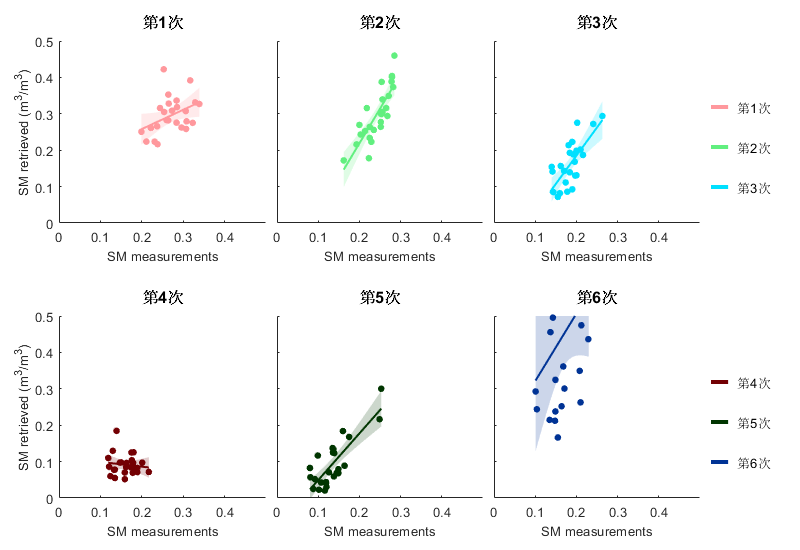

figure('Position',[100 100 800 550]);
g.draw();

% 不同试验次数相关次数
r1 = corrcoef(smWCM(1:25),smMea(1:25))
rmse1 = sqrt(mean((smWCM(1:25)-smMea(1:25)).^2))

r2 = corrcoef(smWCM(26:50),smMea(26:50))
rmse2 = sqrt(mean((smWCM(26:50)-smMea(26:50)).^2))

r3 = corrcoef(smWCM(51:75),smMea(51:75))
rmse3 = sqrt(mean((smWCM(51:75)-smMea(51:75)).^2))

r4 = corrcoef(smWCM(76:100),smMea(76:100))
rmse4 = sqrt(mean((smWCM(76:100)-smMea(76:100)).^2))

r5 = corrcoef(smWCM(101:125),smMea(101:125))
rmse5 = sqrt(mean((smWCM(101:125)-smMea(101:125)).^2))

r6 = corrcoef(smWCM(126:150),smMea(126:150))
rmse6 = sqrt(mean((smWCM(126:150)-smMea(126:150)).^2))

aa = [r1(2),r2(2),r3(2),r4(2),r5(2),r6(2)]
bb = [rmse1,rmse2,rmse3,rmse4,rmse5,rmse6]

r1 = corrcoef(smWCM(1:125),smMea(1:125))
rmse1 = sqrt(mean((smWCM(1:125)-smMea(1:125)).^2))

bias2 = mean(smWCM(126:150)-smMea(126:150))
bias1 = mean(smWCM(1:125)-smMea(1:125))